# Servomecanismos Proyecto Académico

*Isa y los Servotasticos*

clc
clear

## Constantes

Se fijan los valores de a y b para que el trébol mida 15 cm de lado y esté sin rotar (esto se usa más adelante, en el modelo del trébol):

a_min = 1.332; % No cambiar 1.332
b_no_rot = 4.71; % No cambiar 4.71

## Config

### Centros

punto_fijo = [0; 0];
centro_trebol = [25; 25];

#### Largo de eslabones 

Con esto, necesitamos que los eslabones en máxima extensión midan al menos:

lado_trebol_max = 15*1.33;
diagonal_max = hypot(lado_trebol_max, lado_trebol_max);
radio_punto_max = hypot(centro_trebol(1), centro_trebol(2)) + diagonal_max/2

radio_punto_max = 49.4621

Se escogen como primera aproximación para la longitud de los eslabones:

largo_eslabon_1 = 20;
largo_eslabon_2 = 30;

El punto máximo al que llegarán estos eslabones es:

radio_alcance_max = largo_eslabon_1+largo_eslabon_2;

Con esto, es posible llegar a todos los puntos de la trayectoria con las longitudes escogidas para los eslabones. Y se deja una tolerancia de [cm]:

radio_tolerancia = radio_alcance_max - radio_punto_max

radio_tolerancia = 0.5379

#### Escala y rotación

escala = 1; % default = 1
rotacion = 0; % default = 0

### Número de puntos

puntos = 100;

## Forward Kinematics

l1 = Link('revolute', 'd', 0, 'a', largo_eslabon_1, 'alpha', 0);
l2 = Link('revolute', 'd', 0, 'a', largo_eslabon_2, 'alpha', 0);
robot = SerialLink([l1 l2])

 
robot = 
 
noname:: 2 axis, RR, stdDH, slowRNE                              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         20|          0|          0|
|  2|         q2|          0|         30|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


## Inverse Kinematics

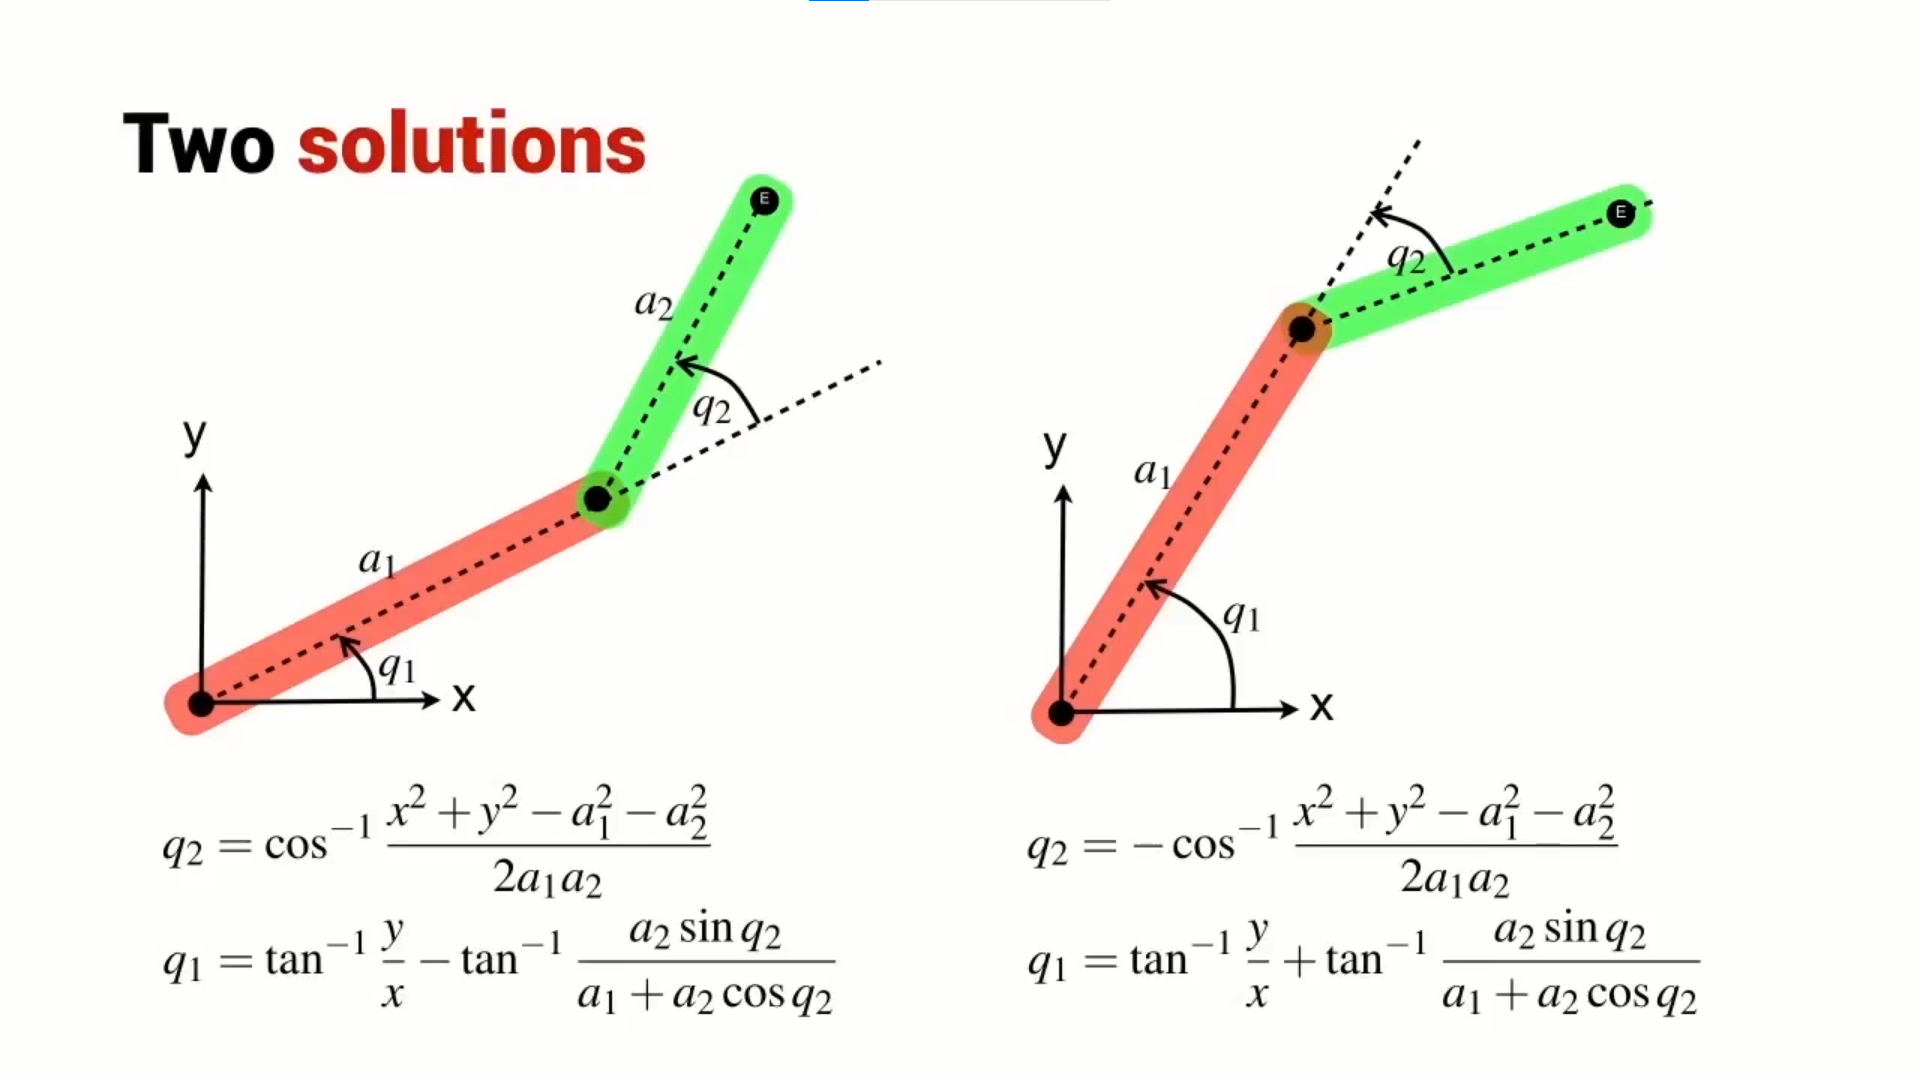

## Trébol

### Definir la trayectoria

syms theta_trebol;
a_trebol = a_min * escala;
b_trebol = b_no_rot + rotacion;
trebol_x(theta_trebol) = (a_trebol*(sin(4*theta_trebol+b_trebol)+6)).*cos(theta_trebol)+centro_trebol(1);
trebol_y(theta_trebol) = (a_trebol*(sin(4*theta_trebol+b_trebol)+6)).*sin(theta_trebol)+centro_trebol(2);

### Discretización de la trayectoria

Si se quiere tener una mejor resolución en la discretización hay que cambiar la variable `intervalo_theta_trebol`. Entre más pequeño el intervalo mejor resolución.

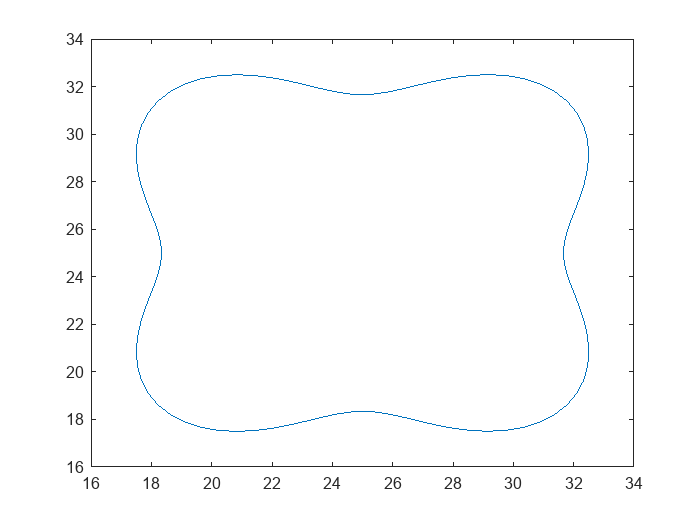

intervalo_theta_trebol = (2*pi)/(puntos);
theta_trebol_discreto = 0:intervalo_theta_trebol:2*pi;
trebol_discretizado_x = trebol_x(theta_trebol_discreto);
trebol_discretizado_y = trebol_y(theta_trebol_discreto);
plot(trebol_discretizado_x, trebol_discretizado_y);

### Cálculo del perímetro

perimetro = 0;
for i = 1:length(trebol_discretizado_x)-1
    % distancia entre puntos consecutivos
    dx = trebol_discretizado_x(i+1) - trebol_discretizado_x(i);
    dy = trebol_discretizado_y(i+1) - trebol_discretizado_y(i);
    distancia = sqrt(dx^2 + dy^2);
    % acumula
    perimetro = perimetro + distancia;
end
perimetro = eval(perimetro)

perimetro = 55.3905

tiempo_recorrido = perimetro/10

tiempo_recorrido = 5.5391

vector_tiempo = linspace(0,tiempo_recorrido,puntos+1)

vector_tiempo =          0    0.0554    0.1108    0.1662    0.2216    0.2770    0.3323    0.3877    0.4431    0.4985    0.5539    0.6093    0.6647    0.7201    0.7755    0.8309    0.8862    0.9416    0.9970    1.0524    1.1078    1.1632    1.2186    1.2740    1.3294    1.3848    1.4402    1.4955    1.5509    1.6063    1.6617    1.7171    1.7725    1.8279    1.8833    1.9387    1.9941    2.0494    2.1048    2.1602    2.2156    2.2710    2.3264    2.3818    2.4372    2.4926    2.5480    2.6034    2.6587    2.7141


## Ángulos para el recorrido

El último ángulo es igual al primero, por eso salen n+1 ángulos para n puntos.

[q1vec, q2vec] = get_angs_multi(largo_eslabon_1, largo_eslabon_2, trebol_discretizado_x, trebol_discretizado_y)

q1vec =     1.4657    1.4604    1.4518    1.4402    1.4263    1.4109    1.3950    1.3798    1.3667    1.3568    1.3515    1.3518    1.3583    1.3714    1.3906    1.4153    1.4442    1.4759    1.5089    1.5418    1.5737    1.6037    1.6312    1.6562    1.6789    1.6997    1.7192    1.7380    1.7571    1.7770    1.7983    1.8214    1.8464    1.8734    1.9019    1.9315    1.9614    1.9907    2.0185    2.0438    2.0659    2.0841    2.0982    2.1082    2.1145    2.1178    2.1192    2.1197    2.1207    2.1230


q2vec =    -1.2945   -1.2745   -1.2505   -1.2223   -1.1902   -1.1549   -1.1175   -1.0796   -1.0431   -1.0102   -0.9829   -0.9634   -0.9531   -0.9531   -0.9632   -0.9826   -1.0098   -1.0427   -1.0791   -1.1170   -1.1545   -1.1899   -1.2220   -1.2503   -1.2744   -1.2945   -1.3110   -1.3248   -1.3368   -1.3483   -1.3604   -1.3741   -1.3905   -1.4101   -1.4333   -1.4601   -1.4902   -1.5229   -1.5574   -1.5926   -1.6275   -1.6611   -1.6924   -1.7209   -1.7464   -1.7687   -1.7884   -1.8061   -1.8228   -1.8394


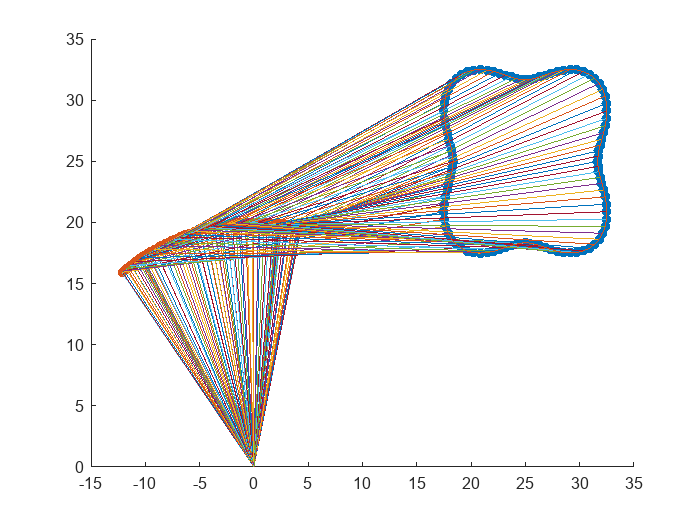

plot_all(trebol_discretizado_x, trebol_discretizado_y, q1vec, q2vec, robot, l1)

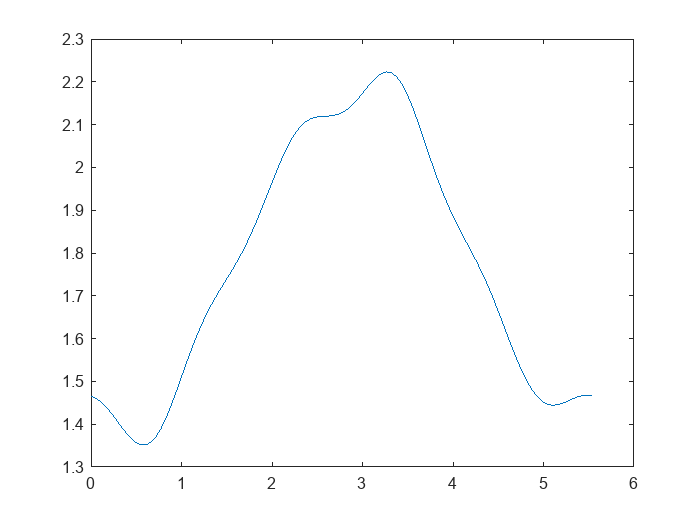

plot(vector_tiempo, q1vec)

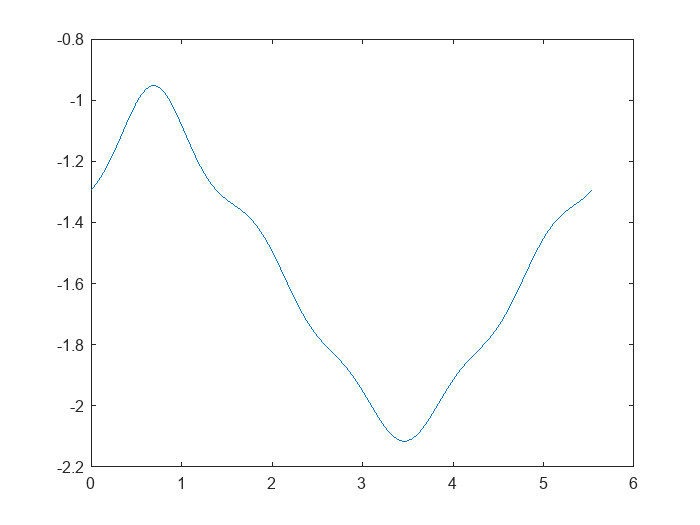

plot(vector_tiempo, q2vec)

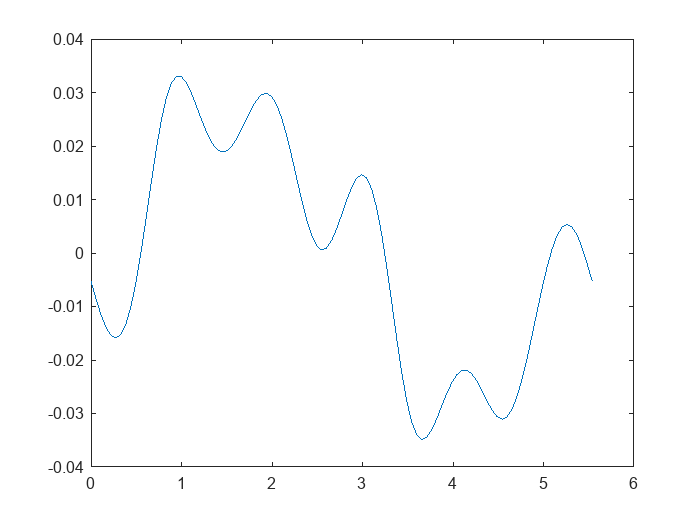

q1vecP = diff(q1vec);
q1vecP(end+1) = q1vecP(1);
plot(vector_tiempo, q1vecP)

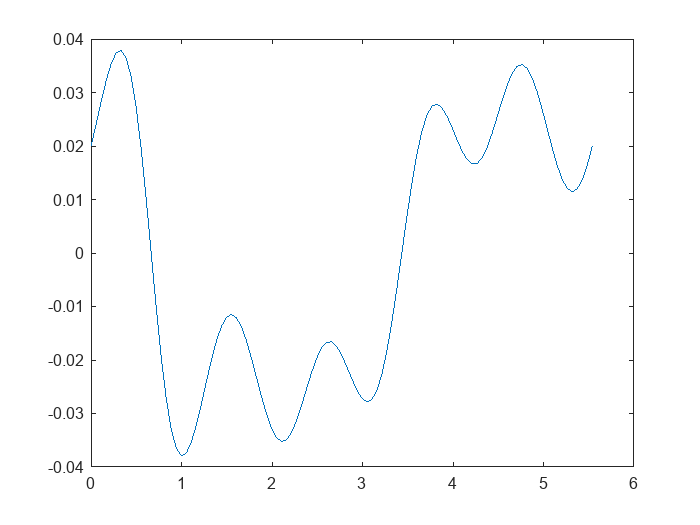

q2vecP = diff(q2vec);
q2vecP(end+1) = q2vecP(1);
plot(vector_tiempo, q2vecP)

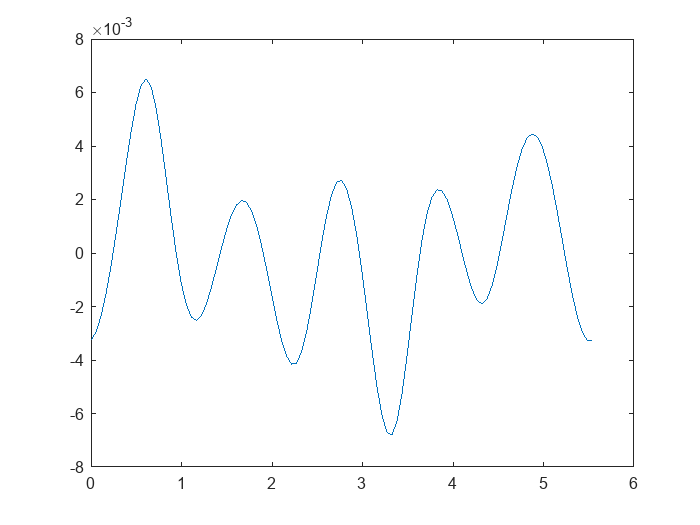

q1vecPP = diff(q1vecP);
q1vecPP(end+1) = q1vecPP(1);
plot(vector_tiempo, q1vecPP)

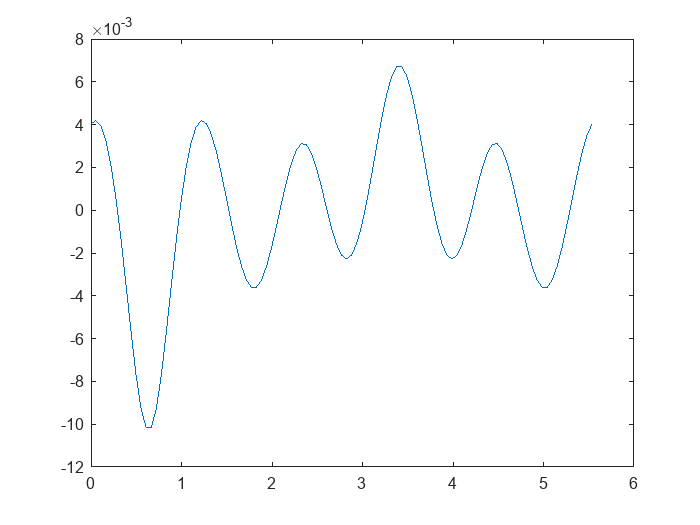

q2vecPP = diff(q2vecP);
q2vecPP(end+1) = q2vecPP(1);
plot(vector_tiempo, q2vecPP)

## Funciones

Esta función se usa para plotear el brazo.

Esta función se usa para plotear el brazo y el trébol. Se pueden comentar algunas líneas dependiendo de la información que se busca.

function plot_all(trebol_x, trebol_y, q1vec, q2vec, robot, l1)
    % tool
    tx = [];
    ty = [];
    for i = 1:length(q1vec)
        onemth = robot.fkine([q1vec(i) q2vec(i)]);
        tx(end+1) = onemth.t(1);
        ty(end+1) = onemth.t(2);
    end
    scatter(tx, ty, 'filled');
    hold on
    % codo
    cx = [];
    cy = [];
    for i = 1:length(q1vec)
        onemth = l1.A([q1vec(i)]);
        cx(end+1) = onemth.t(1);
        cy(end+1) = onemth.t(2);
    end
    scatter(cx, cy, 'filled');
    % linea del origen al codo
    for i = 1:length(cx)
        plot([cx(i), 0], [cy(i), 0]);
    end
    % linea del codo al tool
    for i = 1:length(cx)
        plot([cx(i), tx(i)], [cy(i), ty(i)]);
    end
    % trebol
    plot(trebol_x, trebol_y);
    hold off
end

Cinematica inversa

function [q1, q2] = get_angs(a1, a2, x, y)
    q2 = [acos((x^2+y^2-a1^2-a2^2)/(2*a1*a2)); -acos((x^2+y^2-a1^2-a2^2)/(2*a1*a2))];
    q1 = [atan2(y,x)-atan2((a2*sin(q2)),(a1+a2*cos(q2))); atan2(y,x)+atan2((a2*sin(q2)),(a1+a2*cos(q2)))];
    q1 = q1(1:2);
end

Multi inversa

function [q1vec, q2vec] = get_angs_multi(a1, a2, x, y)
    q1vec = [];
    q2vec = [];
    for i = 1:length(x)
        [q1, q2] = get_angs(a1, a2, x(i), y(i));
        q1vec(end+1) = q1(2); % una de las respuestas se está ignorando
        q2vec(end+1) = q2(2);
    end
end